# Template pour TP/TDM Stats

Dans ce template mlx, vous trouverez du texte, une image, des équations, du code Matlab bien commenté et une jolie figure Matlab, un (petit ici) commentaire sur le résultat obtenu du code, éléments essentiels pour mener à bien votre TP/TDM de stats. Il y a même un hyperlink pour le site duquel est tiré l'image utilisée pour être en accord avec les copyrights.

## Noms des auteurs : 

## Harald CRAMER et Calyampudi Radhakrishna RAO

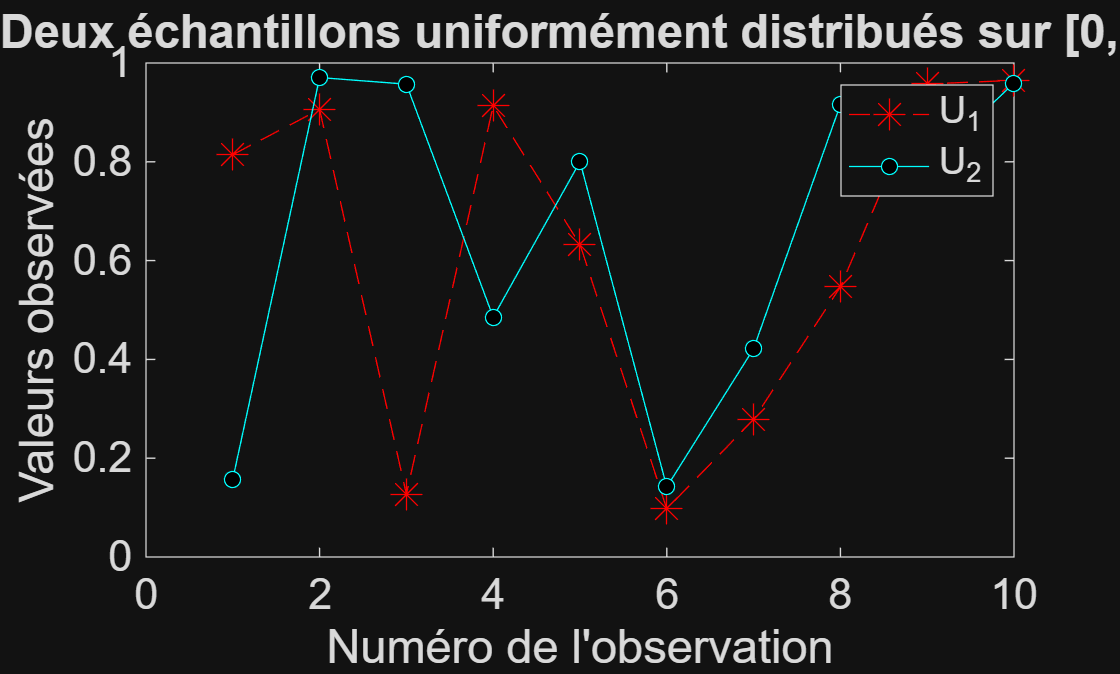

%%% Début du projet : initiation Matlab et les stats
clear all; close all; 
% génération de 2 réalisations de loi uniforme sur (0,1)
nech = 10; % nombre d'observations 
% dans cet exemple, on met nech = 10 pour voir sur la figure
% mais pour faire des stats, 10 observations ne suffisent pas 
U1 = rand(nech,1); % Uniformly distributed random numbers
% attention !
% en regardant le help, si on fait seulement rand(nech),
% on génère une matrice nech x nech
U2 = rand(nech,1);
figure;
plot(U1,'r*--','MarkerSize',12); hold on; plot(U2,'co-','MarkerFaceColor','k');
xlabel('Numéro de l''observation');
ylabel('Valeurs observées');
title('Deux échantillons uniformément distribués sur [0,1]');
legend('U_1','U_2')
ax = gca; ax.FontSize = 16; % règle la fonte du texte sur toute la figure 

On a généré deux vecteurs de taille *nech* . On vérifie bien que les valeurs observées sont entre 0 et 1. Par contre, pour vérifier que ces observations sont représentatives d'une loi uniforme, il faudrait en calculer l'histogramme. On le fera plus tard dans le TP/TDM pour une autre loi. 

On va utiliser l'algorithme de Box-Müller, appelé aussi la transformation de Box-Müller, illustrée sur l'image tirée de [ce site](https://www.algorithm-archive.org/contents/box_muller/box_muller.html).

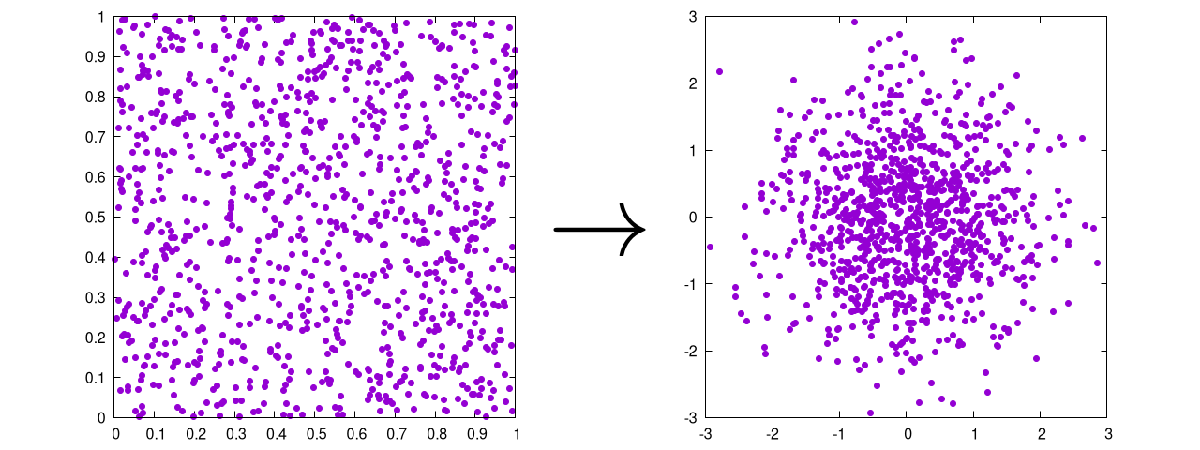

pour générer deux vecteurs de loi gaussienne, centrée, réduite de même taille.

La transformation s'écrit (en faisant "Insert... Equation")


$$X_1 = \sqrt{(-2\ln \left( U_1 \right)}  \cos{\left( 2 \pi U_2 \right)} \\
X_2 = \sqrt{(-2\ln \left( U_1 \right)}  \sin{\left( 2 \pi U_2 \right)}$$


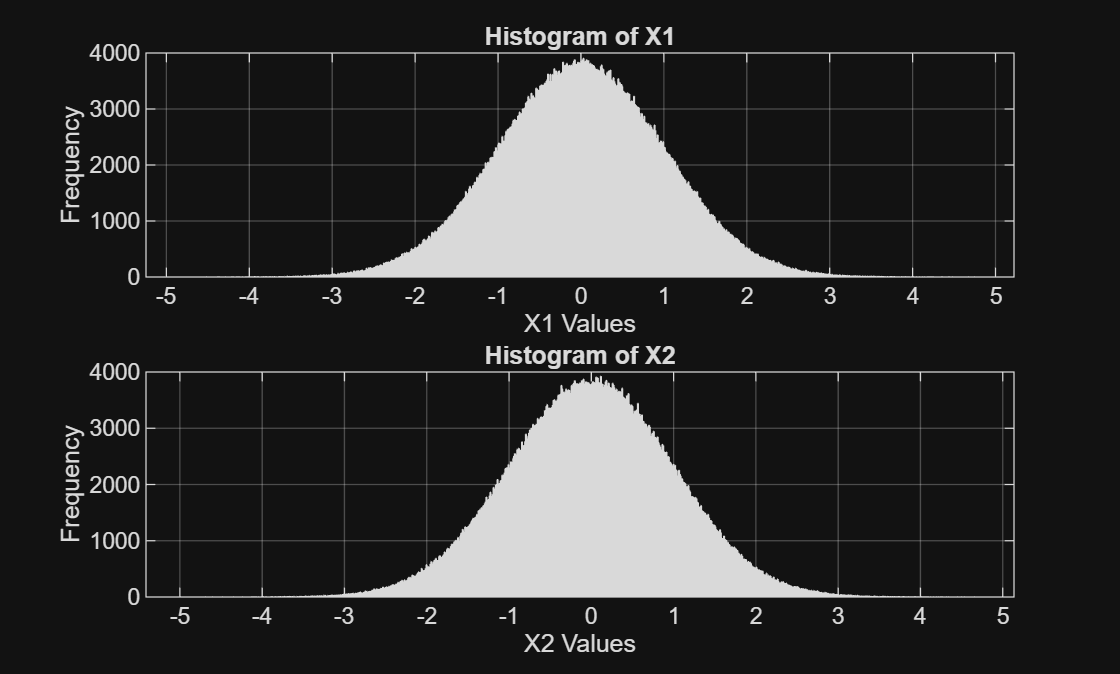

N = 1000; 

U1 = unifrnd(0,1,N);
U2 = unifrnd(0,1,N);

X1 = sqrt(-2 * log(U1)) .* cos(2 * pi * U2); 
X2 = sqrt(-2 * log(U1)) .* sin(2 * pi * U2); 

figure;

subplot(2, 1, 1);
histogram(X1, round(sqrt(N*N)));
title('Histogram of X1');
xlabel('X1 Values');
ylabel('Frequency');
grid on;

subplot(2, 1, 2);
histogram(X2, round(sqrt(N*N)));
title('Histogram of X2');
xlabel('X2 Values');
ylabel('Frequency');
grid on;

2.1 Générer de signaux de test

% Pour vérifier un estimateur, il est nécessaire d'avoir un nombre important de données.
% Nous générons toutes les données selon la même loi, à la même échelle et de même forme.

N = 10000; % Nous voulons que le signal soit étendu sur 10000 données.
K = 500; % Nous voulons reproduire l'expérience sur 500 signaux.
theta = 3.3; 
p = 8;

Y = wblrnd(theta, p, N, K); 
% Génération de la matrice Y de dimensions N*K, où chaque signal contient N données en colonne.
% Toutes les données sont générées aléatoirement selon la loi de Weibull avec les paramètres spécifiés.

mean_Y = mean(Y); % Cela donne une matrice ligne qui représente la moyenne de chaque signal sur N observations.


$$meanY = \frac{1}{N} \sum_{i=1}^{N} Y_{i}$$


var_Y = var(Y);
% Cela donne aussi une matrice ligne mais de la variation de celle ci sur
% 500 signaux à un temps N 

disp(mean_Y);

    3.1062    3.1056    3.1101    3.1094    3.1072    3.1013    3.1092    3.1116    3.1076    3.1024    3.1041    3.1057    3.1119    3.1115    3.1155    3.1066    3.1069    3.1197    3.1059    3.1030    3.1037    3.1061    3.1135    3.1037    3.1068    3.1092    3.1044    3.1144    3.1011    3.1127    3.1043    3.1101    3.1091    3.1048    3.1092    3.1087    3.1047    3.1087    3.1042    3.1049    3.1090    3.1121    3.1144    3.1067    3.1126    3.1040    3.1109    3.1146    3.1145    3.1034    3.1113    3.1042    3.1162    3.1069    3.1105    3.1026    3.1113    3.1120    3.1055    3.1156    3.1096    3.1094    3.1098    3.1013    3.1134    3.1016    3.1020    3.1045    3.1040    3.1018    3.1040    3.1035    3.1018    3.1064    3.1079    3.1076    3.1106    3.1108    3.1044    3.1098    3.1118    3.1121    3.1084    3.1120    3.1119    3.1140    3.1107    3.1117    3.1140    3.1000    3.1022    3.1101    3.1097    3.1111    3.1041    3.1103    3.1060    3.1063    3.0999    3.1196

disp(var_Y);

    0.2105    0.2141    0.2148    0.2083    0.2155    0.2164    0.2107    0.2098    0.2136    0.2131    0.2052    0.2158    0.2109    0.2177    0.2123    0.2142    0.2112    0.2101    0.2155    0.2168    0.2142    0.2086    0.2073    0.2159    0.2141    0.2130    0.2125    0.2109    0.2126    0.2115    0.2095    0.2085    0.2154    0.2137    0.2146    0.2096    0.2117    0.2128    0.2142    0.2131    0.2115    0.2150    0.2132    0.2141    0.2120    0.2122    0.2178    0.2114    0.2059    0.2124    0.2090    0.2188    0.2145    0.2131    0.2119    0.2172    0.2109    0.2110    0.2162    0.2084    0.2114    0.2147    0.2167    0.2119    0.2072    0.2105    0.2207    0.2140    0.2122    0.2116    0.2157    0.2131    0.2120    0.2092    0.2147    0.2126    0.2178    0.2119    0.2099    0.2090    0.2147    0.2113    0.2153    0.2141    0.2103    0.2091    0.2132    0.2089    0.2105    0.2127    0.2137    0.2138    0.2103    0.2177    0.2127    0.2182    0.2092    0.2117    0.2153    0.2176

% Mais ce que nous dit la loi de Weibull c'est que avec l'échelle theta et
% la forme p on peut trouver la moyenne théorique grace à la formule 

t_mean = theta * gamma(1 + 1/p); 
disp(t_mean); % 3.1078

    3.1078



t_variance = (theta^2) * (gamma(1 + 2/p) - (gamma(1 + 1/p))^2);
disp(t_variance); %0.2126

    0.2126



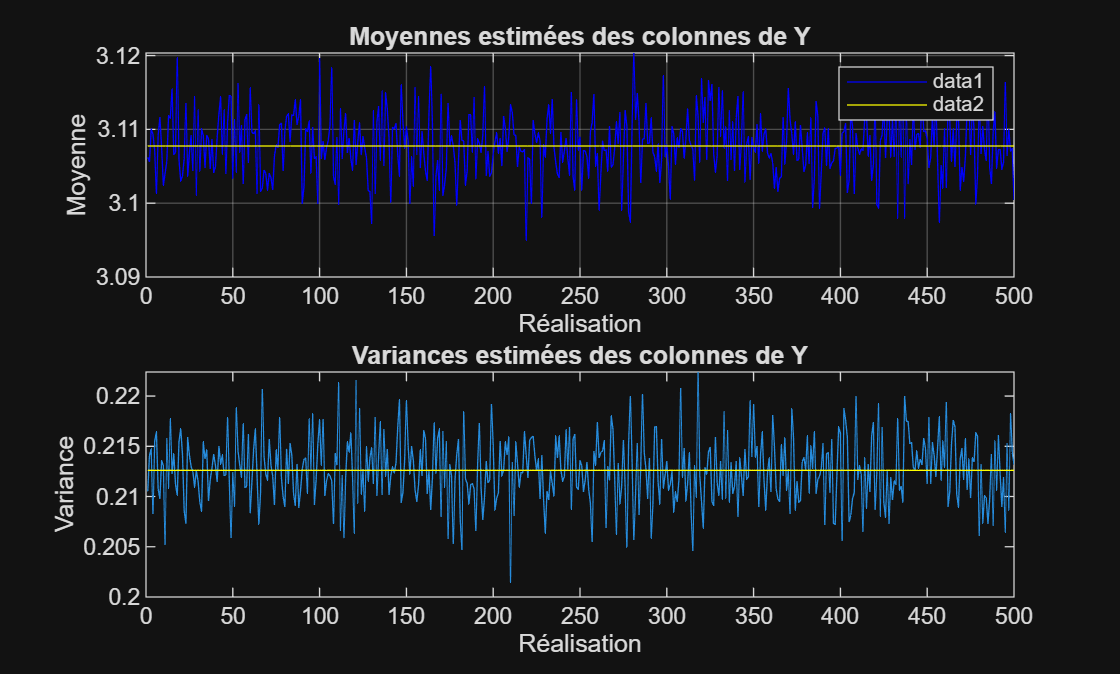

figure;
subplot(2, 1, 1);
plot(mean_Y, 'b');
hold on; 
MvVar_matrix = repmat(t_mean, K, 1); % Créer une matrice de t_mean avec K lignes
plot(MvVar_matrix', 'y'); % Tracer la matrice t_mean
hold off; 

grid on;
title('Moyennes estimées des colonnes de Y');
xlabel('Réalisation');
ylabel('Moyenne');
legend;

subplot(2, 1, 2);
plot(var_Y);
hold on;
t_var_matrix = repmat(t_variance, K, 1);
plot(t_var_matrix, 'y')
title('Variances estimées des colonnes de Y');
xlabel('Réalisation');
ylabel('Variance');

On peut voir que les moyennes ne sont pas parfaitement le résultat attendu mais ne diverge pas complètement ce qui différencie de la valeur obtenu de la théorie. C'est que la théorie montre pour un nombre de donnée infini tels que le résultat devrait forcément converger vers une valeur unique qui est la moyenne de la loi. Ici la quantité de donnée nous permet de dire que les valeur de moyenne et variance sont proche de la valeur attendu théorique et que si on avait une infinité de donnée alors on finirait par avoir une ligne droite suivant la valeur théorique. 

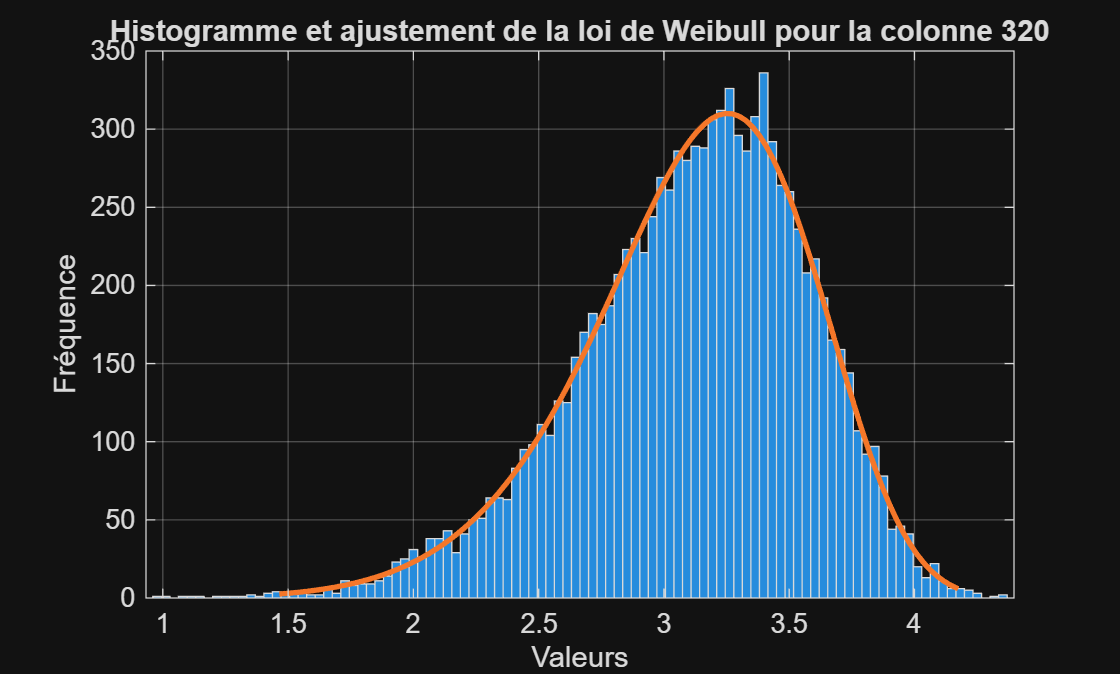


figure;
random_col = randi(K); 
histfit(Y(:, random_col), round(sqrt(N)), 'weibull');
title(['Histogramme et ajustement de la loi de Weibull pour la colonne ' num2str(random_col)]);
xlabel('Valeurs');
ylabel('Fréquence');
grid on;

On peut voir sur le graphique que la courbe épouse parfaitement les colonnes de l'histogramme cela signifie que on a bien une expérience avec des données représentatif de la loi de Weibull 

2.2 

% Calcul de l'espérance E[X] pour une variable aléatoire suivant une loi de Weibull
% E[X] = theta * gamma(1 + 1/p) = bar(Xn)
% On remplace m1 par ^thetaMo = bar(Xn) / gamma(1 + 1/p) avec p = 8
% bar(XN) / gamma(9/8) = ^thetaMo
% theta * gamma(9/8) /gamma(9/8) = theta = ^thetaMo

% Estimation sans biais de E[^thetaMo] = theta, donc BthetaMo = E[^thetaMo] - theta = 0

theta_MmoK = (1/(N*gamma(1+1/p)))*sum(Y,1);
% On a mean_Mmo qui est une matrice des valeur de theta pour chacun des K
% réalisation il devrait tous être proche de la valeur théorique de
% ^thetaMo

figure;
subplot(2, 1, 1);
plot(theta_MmoK, 'b', 'DisplayName','variation obtenu')
hold on; 
MvVar_matrix = repmat(theta, K, 1);
plot(MvVar_matrix, 'y', 'DisplayName','valeur théorique'); 
hold off;

grid on;
title('Différence valeur attendu et valeur théorique ');
xlabel('Réalisation');
ylabel('theta');
legend;

ans_theta=mean(theta_MmoK);

% Estimation de la variance de E[^thetaMo]
var_Mmo = var(theta_MmoK);


thetaMV=mean(Y.^p).^(1/p);

% On a dit que l'estimateur est sans biais et que donc E[^thetaMV]=theta et
% que donc mean(thetaMV)=theta

precision_diff = abs(mean(thetaMV) - theta);
text(1, mean(thetaMV) + 0.05, ['Différence de précision: ' num2str(precision_diff)], 'HorizontalAlignment', 'center', 'Color', 'r', 'FontSize', 12);


On voit bien que les données se situe dans autour de la valeur théorique 

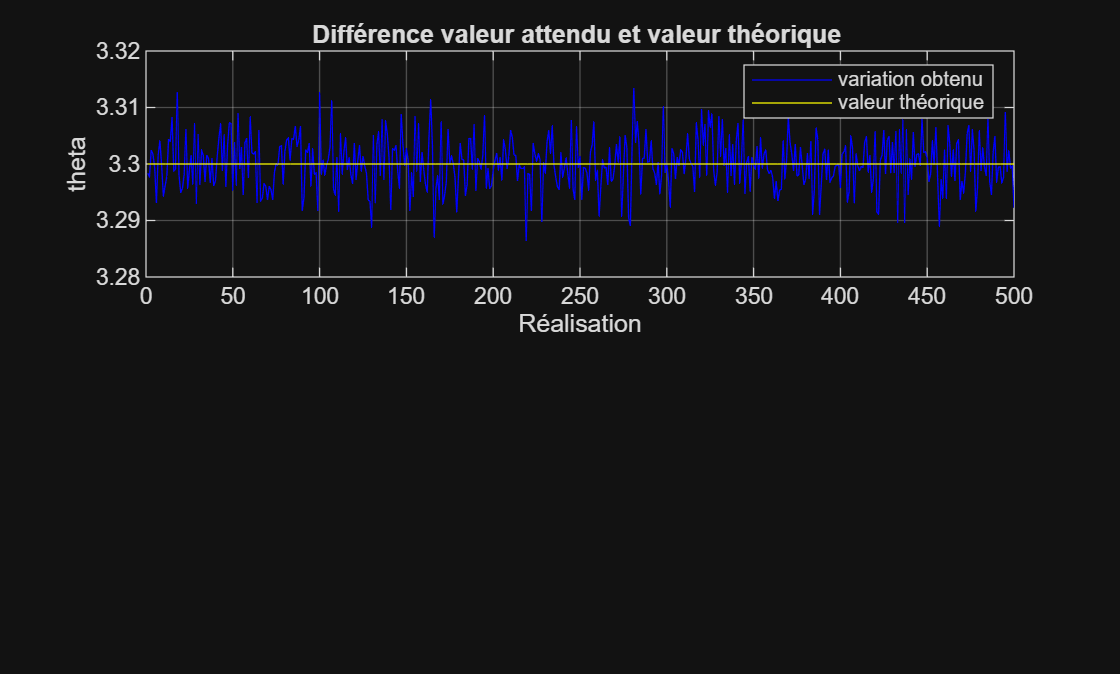

grid on;

% Estimation de l'erreur quadratique moyenne (EQM) pour les estimateurs
mse_theta_Mmo = mean((theta_MmoK - theta).^2);
mse_thetaMV = mean((thetaMV - theta).^2);

% Affichage des résultats de l'estimation de l'erreur quadratique moyenne (EQM)
disp(['EQM pour l''estimateur de Mmo: ', num2str(mse_theta_Mmo)]);

EQM pour l'estimateur de Mmo: 2.0671e-05


disp(['EQM pour l''estimateur de MV: ', num2str(mse_thetaMV)]);

EQM pour l'estimateur de MV: 1.5349e-05


i_values = 1000:1000:N;
Ntheta_MmoK = zeros(length(i_values), K);
Ntheta_Mv   = zeros(length(i_values), K);

for idx = 1:length(i_values)
    i = i_values(idx);
    Y = wblrnd(theta, p, i, K);
    Ntheta_MmoK(idx,:) = (1/(i*gamma(1+1/p)))*sum(Y,1);
    Ntheta_Mv(idx,:) = mean(Y.^p, 1).^(1/p);
end

BCR_matrix = repmat((theta^2)/(N*p^2),N,1);
figure;
subplot(2, 1, 1);
plot(i_values, var(Ntheta_Mv,0,2), 'b', 'DisplayName','Var MV');
hold on;
plot(BCR_matrix, 'r', 'LineStyle', '--', 'DisplayName', 'BCR');
plot(i_values, var(Ntheta_MmoK,0,2), 'y', 'DisplayName','Var Mom');
hold off;
grid on;
title('Variance des estimateurs selon N');
xlabel('N = taille de l échantillon');
ylabel('Variance');

On voit bien que le MV et Mom sont bien supérieur à BCR et que par conséquent ils sont non biaisé.

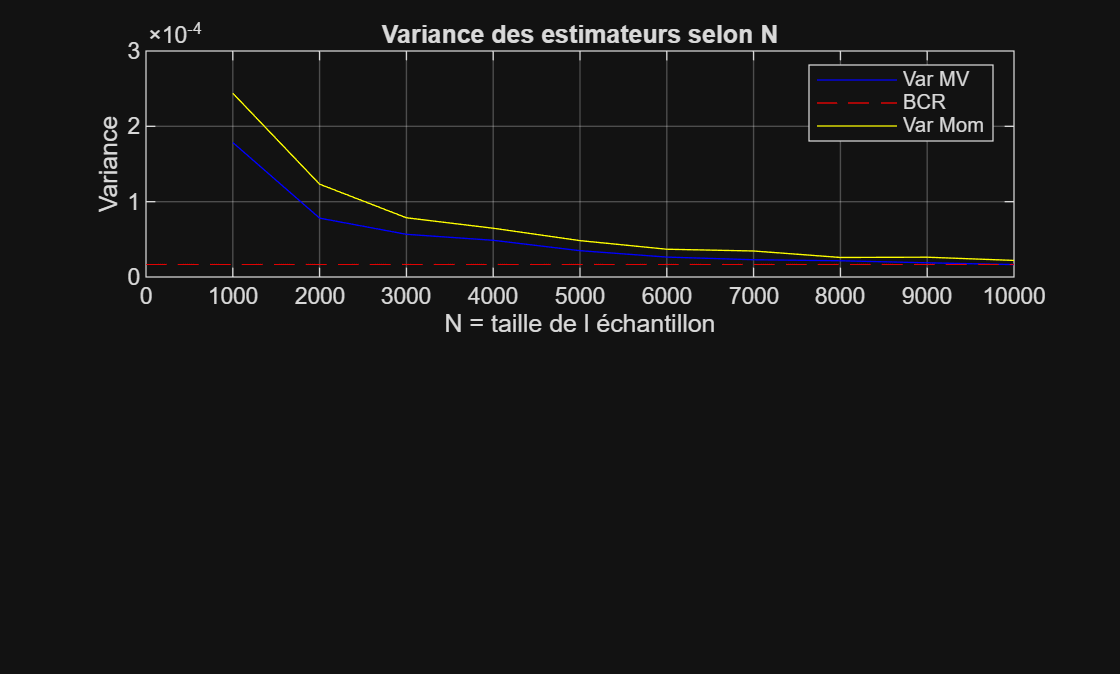

legend;

2.3 Détection

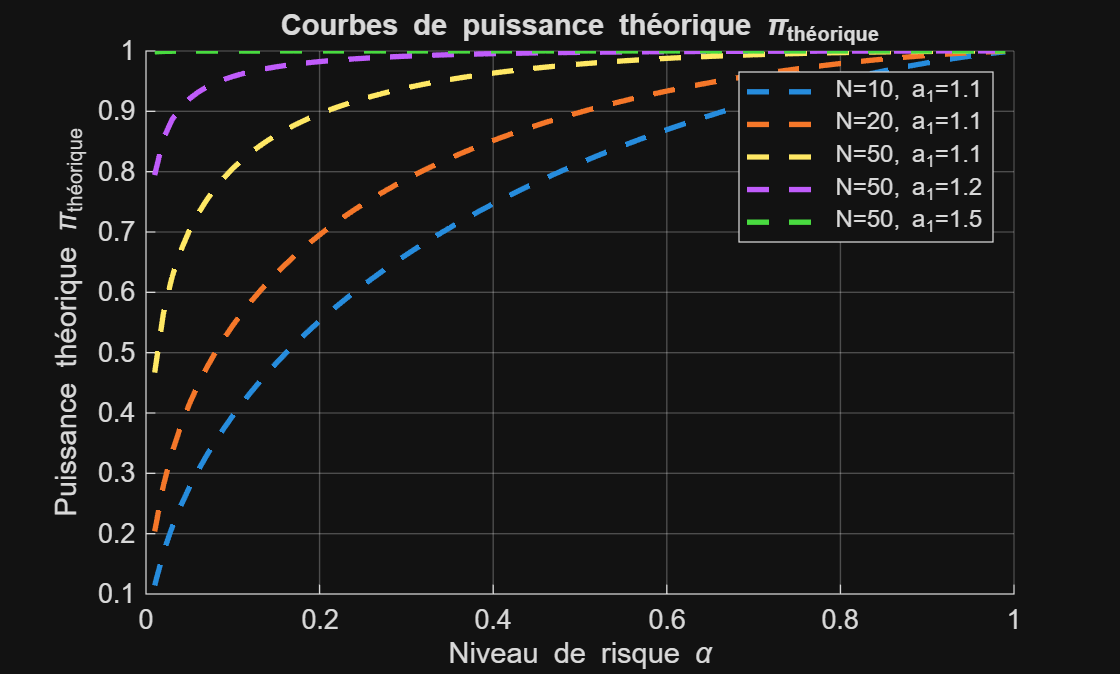

theta0 = 0.9;
p = 1.5;
alpha = 0.01:0.01:0.99;
N_values = [10 20 50,50,50];
a1_values = [1.1 1.1 1.1 1.2 1.5]; 
K = 1000; 

figure; hold on;
for i = 1:length(N_values)
    N = N_values(i);
    a1 = a1_values(i);
    a0 = theta0^p;
    a1power = a1^p;
    lambdaA = (a0 / 2) * chi2inv(1 - alpha, 2 * N);
    beta = chi2cdf((2 * lambdaA) / a1power, 2 * N);
    pi_th = 1 - beta;
    plot(alpha, pi_th, '--', 'LineWidth', 2, ...
        'DisplayName', ['N=' num2str(N) ', a_1=' num2str(a1)]);
end
hold off;
grid on;
title('Courbes de puissance théorique \pi_{théorique}');
xlabel('Niveau de risque \alpha');
ylabel('Puissance théorique \pi_{théorique}');
legend('show');

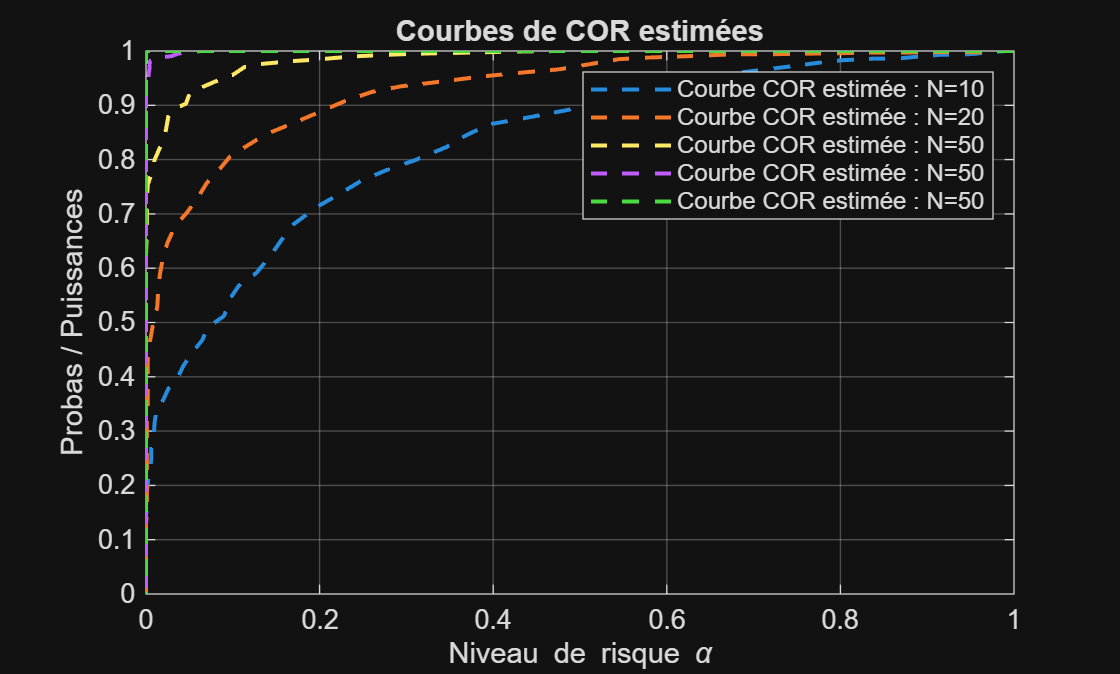

for i = 1:length(N_values)
    N = N_values(i);
    a0 = theta0^p;
    a1 = a1_values(i);
    a1power = a1^p;
    Y0 = wblrnd(a0, p, N, K); 
    Y1 = wblrnd(a1power, p, N, K);
    T0 = sum(Y0.^p, 1); 
    T1 = sum(Y1.^p, 1);
    seuils = linspace(min([T0, T1]), max([T0, T1]), length(alpha));
    fausse_alarme = zeros(size(seuils));
    puissance_exp = zeros(size(seuils));
    for j = 1:length(seuils)
        seuil = seuils(j);
        fausse_alarme(j) = mean(T0 > seuil);
        puissance_exp(j) = mean(T1 > seuil);
    end
    plot(fausse_alarme, puissance_exp, '--', 'LineWidth', 1.5, 'DisplayName', ...
    ['Courbe COR estimée : N=' num2str(N)]);
    hold on;
end
hold off;
xlabel('Niveau de risque \alpha');
ylabel('Probas / Puissances');
legend('show');
title('Courbes de COR estimées');
grid on;

2.4

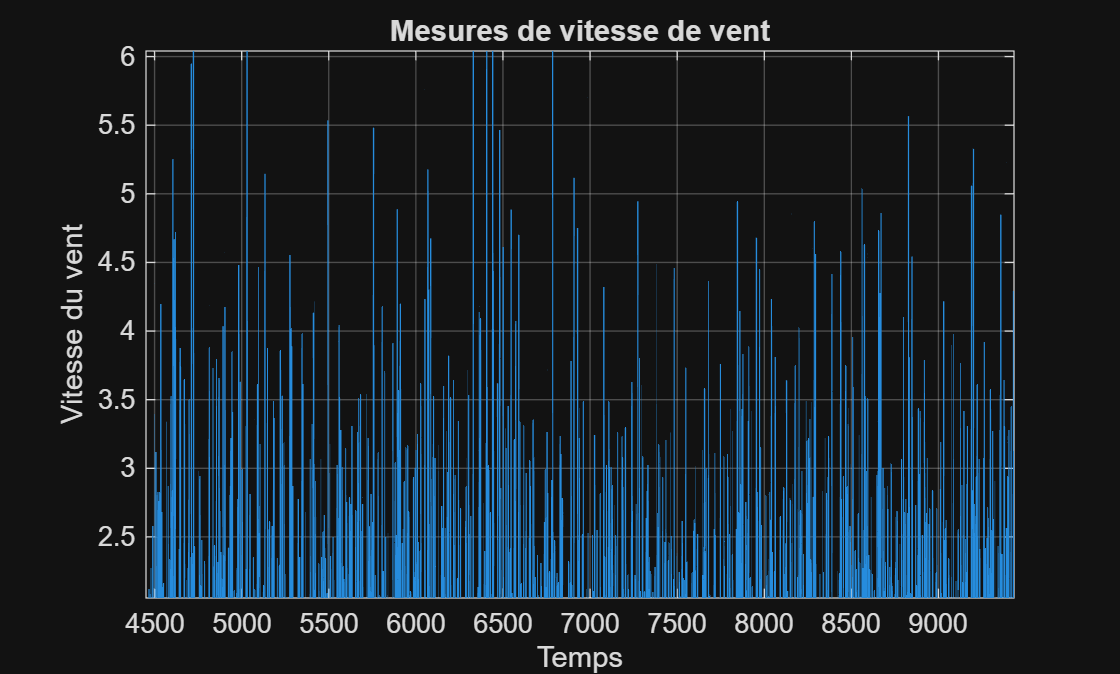

% Question 1 : Charger et représenter les données
load('C:\Users\quent\Documents\MATLAB\wind.mat');
figure;
plot(test);
title('Mesures de vitesse de vent');
xlabel('Temps');
ylabel('Vitesse du vent');
grid on;

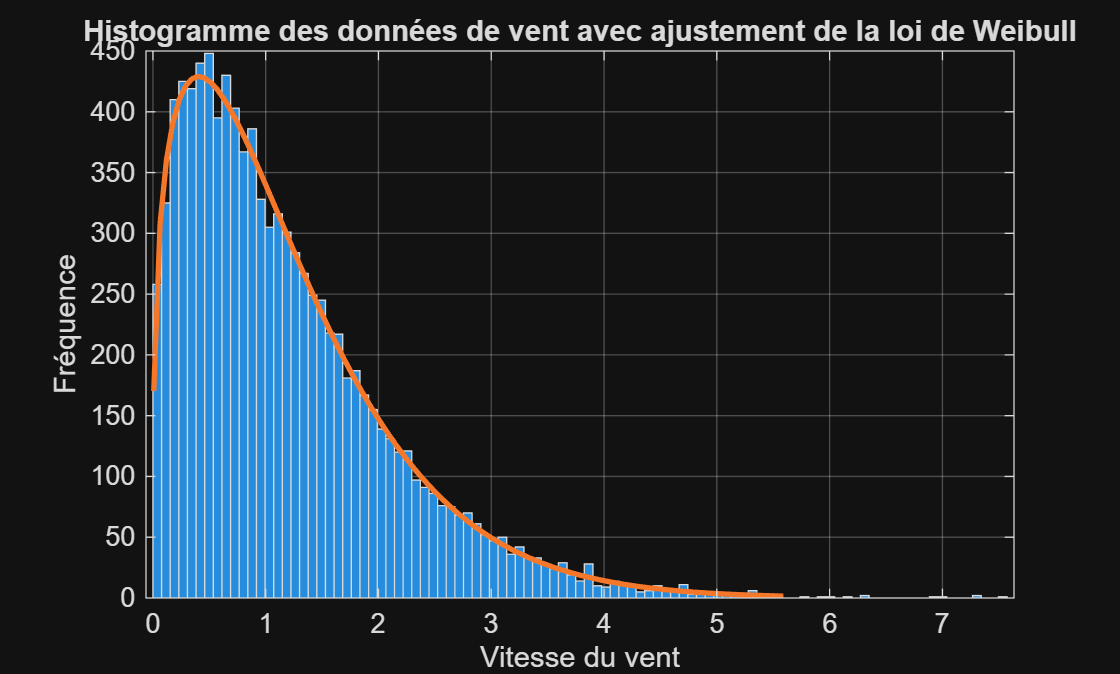


% Question 2 : Histogramme avec ajustement Weibull
figure;
histfit(test, round(sqrt(length(test))), 'weibull');
title('Histogramme des données de vent avec ajustement de la loi de Weibull');
xlabel('Vitesse du vent');
ylabel('Fréquence');
grid on;

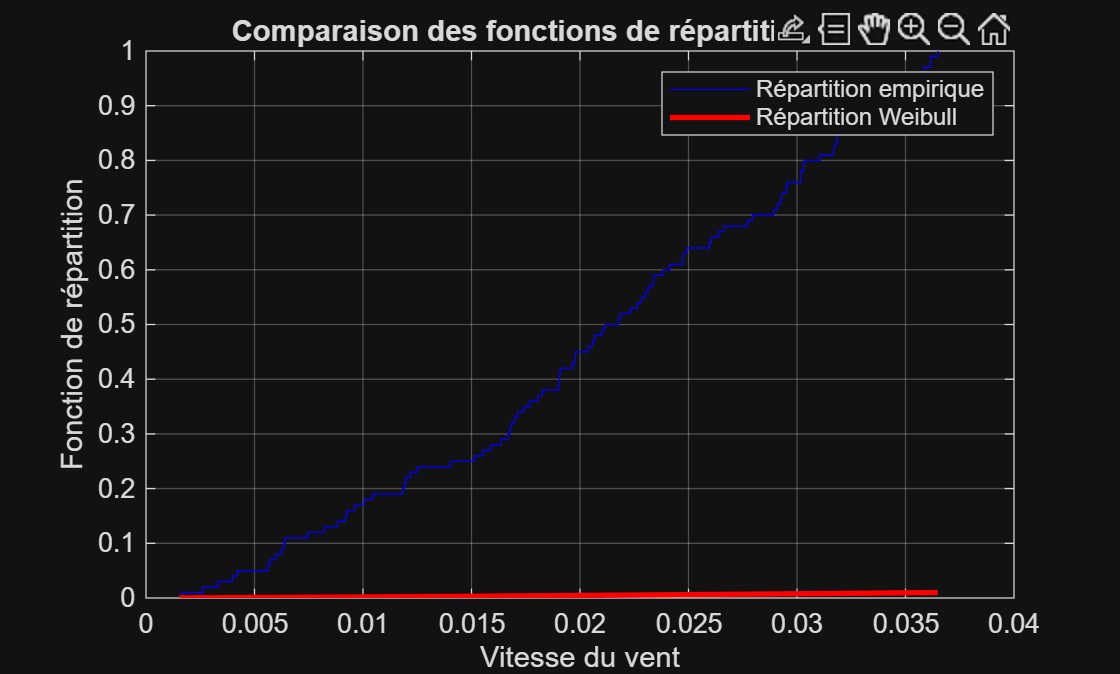


% Question 3 : Test de Kolmogorov
% Estimation des paramètres de la loi de Weibull
params = wblfit(test(:));
hat_theta = params(1);
hat_p = params(2);

% Représentation des fonctions de répartition (N=100 d'abord)
sorted_data = sort(test);
N_total = length(sorted_data);

% Avec N = 100 données
figure;
N = 100;
sorted_data_100 = sorted_data(1:N);
y_empirical_100 = (1:N) / N;
F_w_100 = wblcdf(sorted_data_100, hat_theta, hat_p);

stairs(sorted_data_100, y_empirical_100, 'b', 'DisplayName', 'Répartition empirique');
hold on;
plot(sorted_data_100, F_w_100, 'r', 'LineWidth', 2, 'DisplayName', 'Répartition Weibull');
hold off;
title('Comparaison des fonctions de répartition (N=100)');
xlabel('Vitesse du vent');
ylabel('Fonction de répartition');
legend;
grid on;

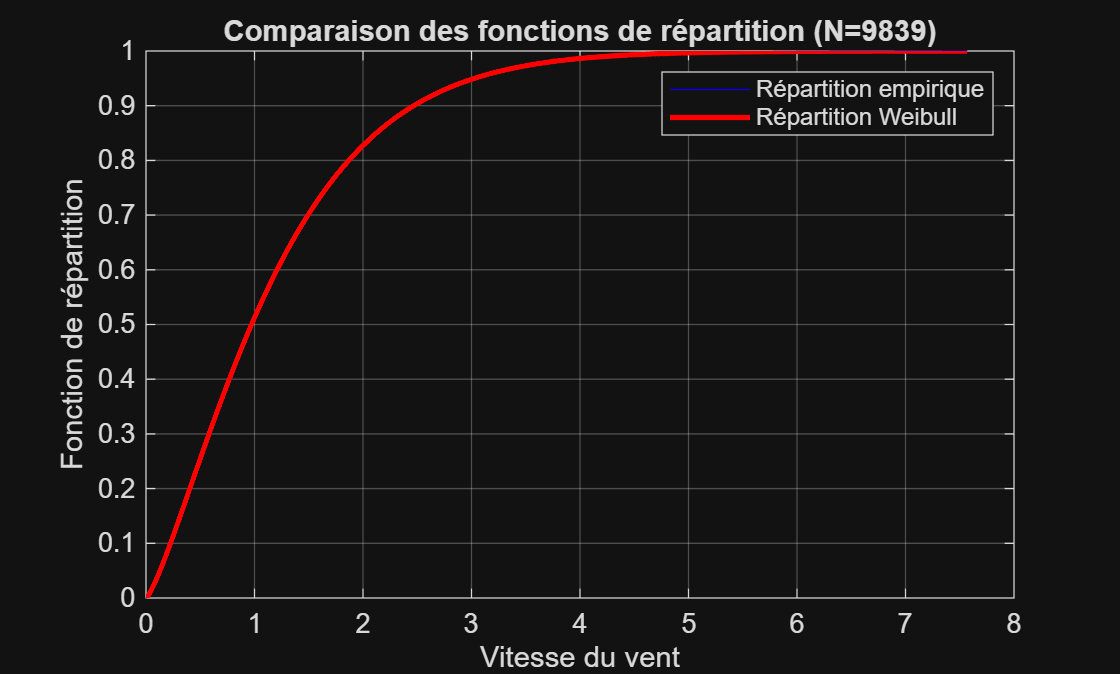


% Avec toutes les données
figure;
N = N_total;
y_empirical = (1:N) / N;
F_w = wblcdf(sorted_data, hat_theta, hat_p);

stairs(sorted_data, y_empirical, 'b', 'DisplayName', 'Répartition empirique');
hold on;
plot(sorted_data, F_w, 'r', 'LineWidth', 2, 'DisplayName', 'Répartition Weibull');
hold off;
title(['Comparaison des fonctions de répartition (N=', num2str(N), ')']);
xlabel('Vitesse du vent');
ylabel('Fonction de répartition');
legend;
grid on;